# Twin Study

# Group Assignment

# Comparison of two Data sets

**In a study we test the lifespan of 10 pairs of twins. Where one have been smoking and the other have not.**

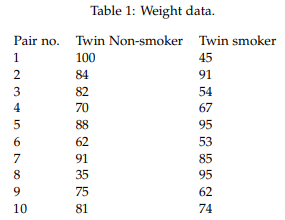

twin_non_smoker_weight = [100, 84, 82, 70, 88, 62, 91, 35, 75, 81 ];
twin_smoker_weight = [45, 91, 54, 67, 95, 53, 85, 95, 62, 74];

**In this assignment, you have to find out what test to perform to compare the two sample sets. You should answer the following questions:**

1. Estimate the mean and the variance of the population samples.

mean(twin_smoker_weight);
Mean_smoker_Form=sum(twin_smoker_weight)./length(twin_smoker_weight);
mean(twin_non_smoker_weight);
Mean_non_smoker_form=sum(twin_non_smoker_weight)./length(twin_non_smoker_weight);
var(twin_smoker_weight);
var_smoker_form=1/(length(twin_smoker_weight)-1).*sum((twin_smoker_weight-Mean_smoker_Form).^2);
var(twin_non_smoker_weight);
var_non_smoker_form=1/(length(twin_non_smoker_weight)-1).*sum((twin_non_smoker_weight-Mean_non_smoker_form).^2);

2. Find the mean of difference of the population samples.

delta = twin_smoker_weight - twin_non_smoker_weight;
mean(delta);
mean_delta = (sum(delta)./length(delta));

3. Formulate the NULL hypothesis to test wether the two samples comes from populations with the same mean.

4. Formulate the alternative hypothesis to the NULL hypothesis.

$H_0 =\mu_1 =\mu_2$, $H_1 =\mu_1 \not= \mu_2$

or 

$H_0 =\delta =0$, $H_1 =\delta \not= 0$

5. What statistical test would would you perform to test the hypothesis?

 I would use Paired test t-test, as the variance is unknown, and the data is paired

6. Calculate the test-statistics. 

% Variance
est_sample_var = (1/(length(delta)-1)).*(sum((delta-mean_delta).^2));
% deviance
est_sample_dev = sqrt(est_sample_var);
test_size = mean_delta / (est_sample_dev / sqrt(length(delta)));
p_val = 2 * (1 - tcdf(abs(test_size), length(delta) - 1))

p_val = 0.6220

Since the p-value is above 0.05, we cannot reject the null hypothesis

lower_bound = mean_delta - tinv(0.975, length(delta) - 1) * est_sample_dev/sqrt(length(delta))

lower_bound = -25.5289

upper_bound = mean_delta + tinv(0.975, length(delta) - 1) * est_sample_dev/sqrt(length(delta))

upper_bound = 16.1289

7. Should the test be paired or unpaired?

Looking at the slides

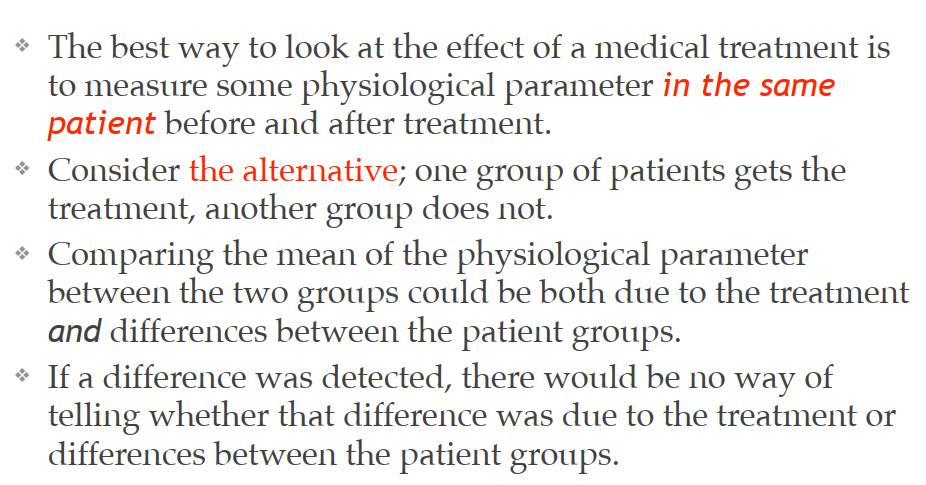

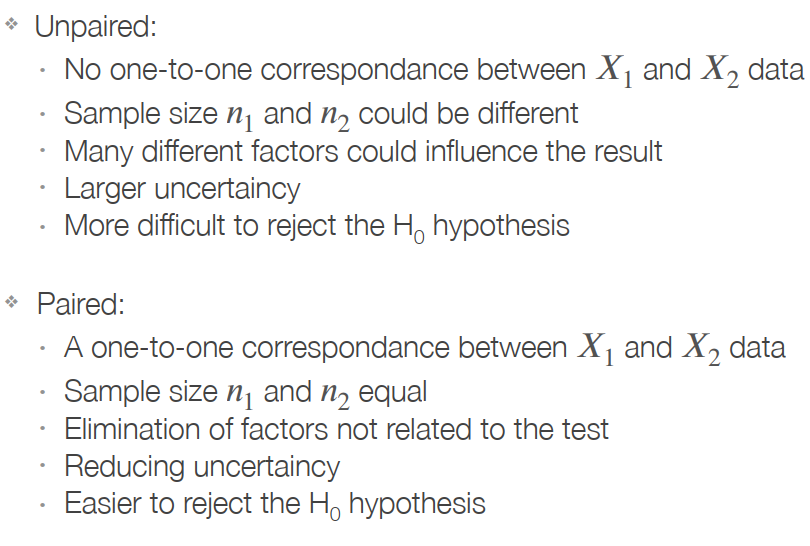

Tip for the exam. See what makes sense in the dataset, and then explain your thoughts and how you came to the solution. She might write a clear hint as to which one to choose, but it may be very hard, and therefore you need to do it on your own and explain your thought (get some bonus points for your solution)

8. Can you based on you chosen statistical test, reject the hypothesis?

No since the mean is in between the lower and upper bounds of delta, the null hypothesis cannot be rejected

9. Do yo get a difference for paired and un-paired tests? 

unpaired test used pooled variance (s.65 i formelsamling)

pool_var = (1/(length(twin_non_smoker_weight)+length(twin_smoker_weight)-2))*( (length(twin_non_smoker_weight)-1) * var_non_smoker_form + (length(twin_smoker_weight) - 1) * var_smoker_form);
pool_dev = sqrt(pool_var);
test_size_unpaired = (Mean_non_smoker_form - Mean_smoker_Form) / (pool_dev * sqrt((1/length(delta)) + 1/length(delta)));
p_val_unpaired = 2 * (1 - tcdf(abs(test_size_unpaired), length(delta) * 2 - 2));

There is a slight difference, but the null hypothesis can still not be rejected since p > 0.05. The conclusion is the same as with the paired test

10. Find the 95% confidence interval for the difference in the means. 

lower_bound_unpaired = (Mean_non_smoker_form - Mean_smoker_Form) - tinv(0.975, 20 - 2) * pool_dev * sqrt(1/5)

lower_bound_unpaired = -12.6084

upper_bound_unpaired = (Mean_non_smoker_form - Mean_smoker_Form) + tinv(0.975, 20 - 2) * pool_dev * sqrt(1/5)

upper_bound_unpaired = 22.0084

11. Based on a the samples, what would the difference of the population means? 

I do not understand this question, but apparently the same answer as 2?